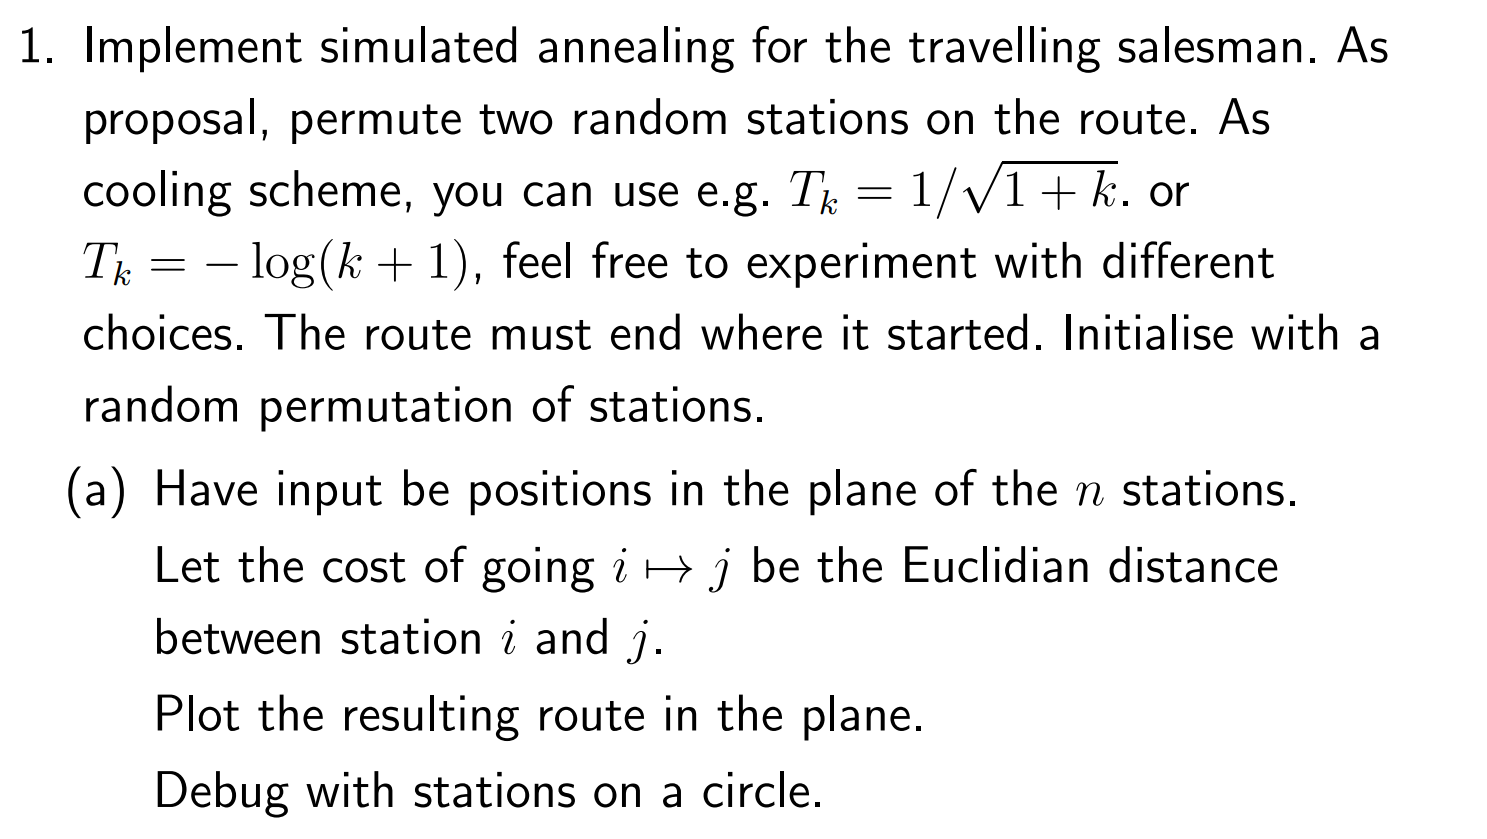

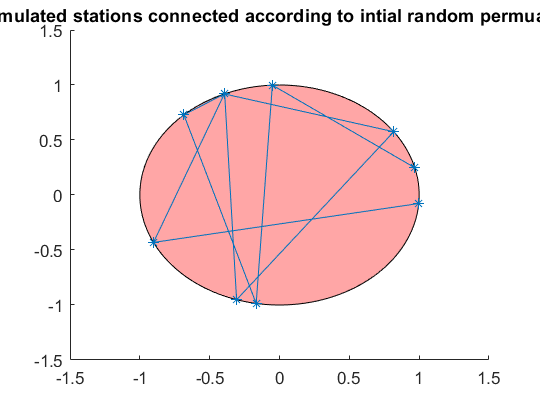

clc;clear;close all;

T = @(k) 1/sqrt(1+k); % cooling scheme

m = 10; %n - stations
angl = rand(m,1);
points = [sin(2*pi*angl),cos(2*pi*angl)];
S = randperm(m);
figure;
hold on
p = nsidedpoly(1000, 'Center', [0 0], 'Radius', 1);
plot(p, 'FaceColor', 'r')
plot(points(S,1),points(S,2),'*-')
title("Simulated stations connected according to intial random permuation")
hold off
saveas(gcf,'ex7_a_random.png')

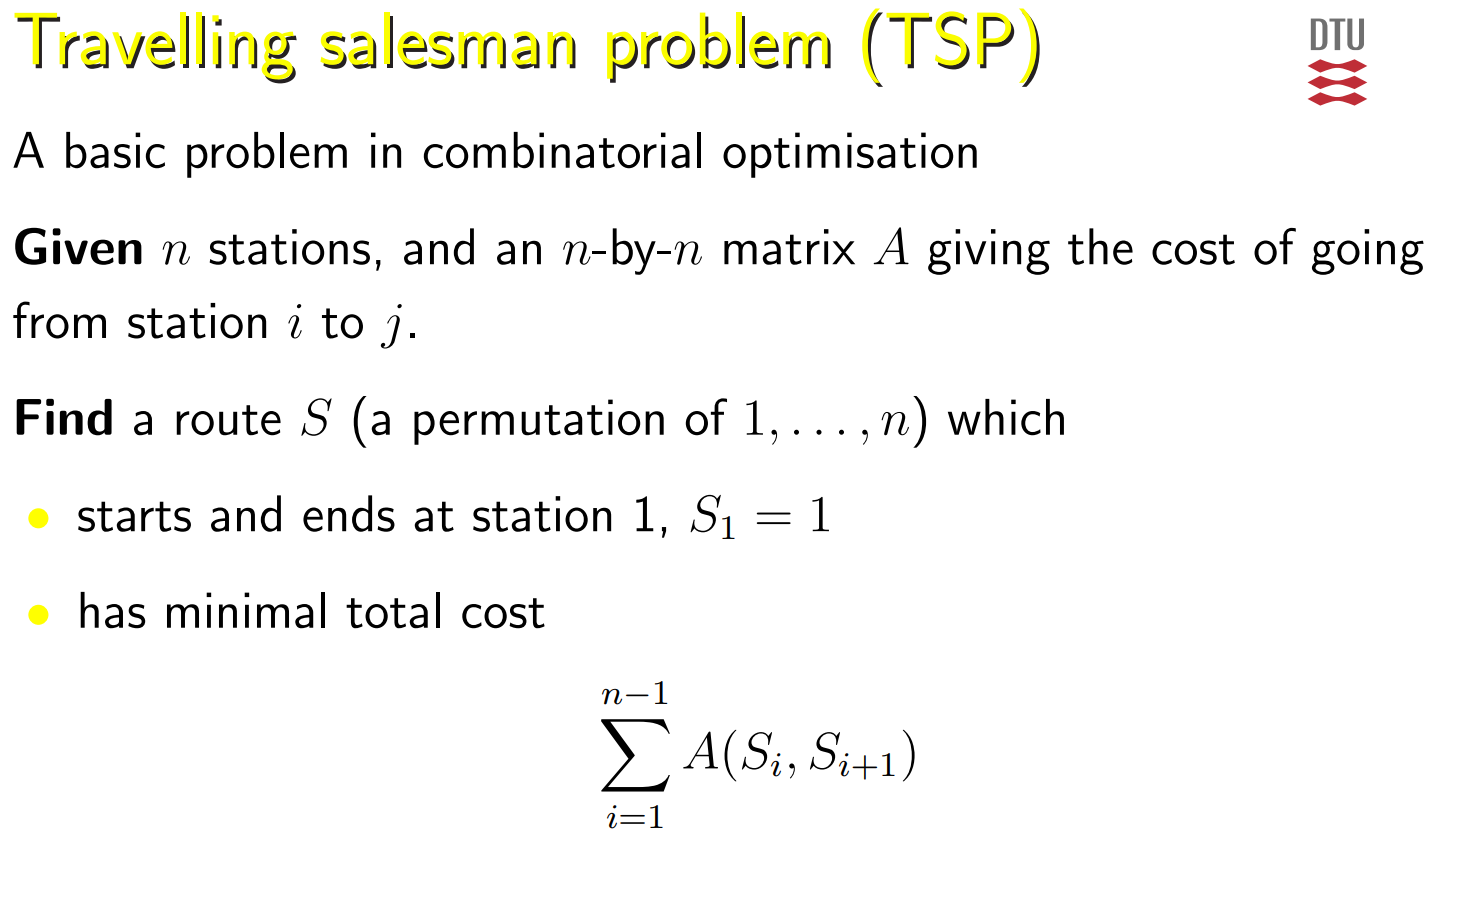

A = squareform(pdist(points));
S = randperm(m);
U =@(S) U_ecd(A,S);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%Algorithm starts%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


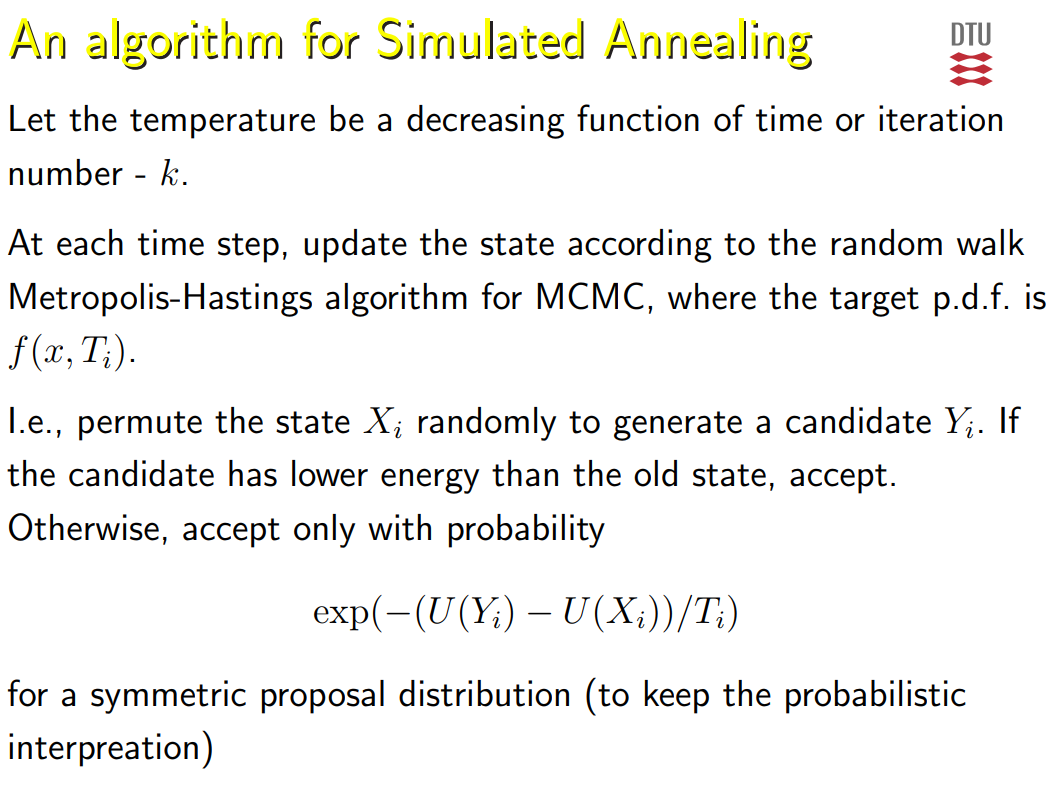

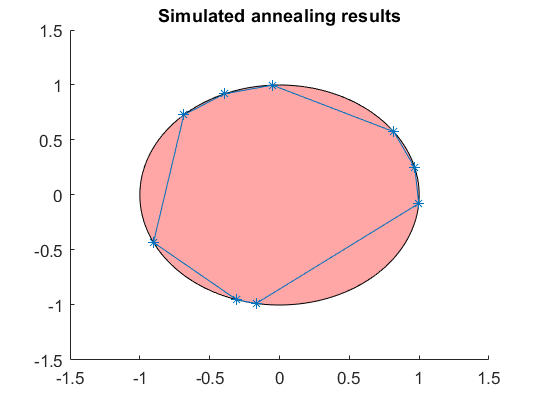

k = 100000; %number of iterations
X = zeros(k,m);
X(1,:) = S;
for i = 1:k
    %%%%%Permutation%%%%%%
    Y = X(i,:);
    p = randperm(m,2);
    Sp1 = Y(p(2));
    Sp2 = Y(p(1));
    Y(p(1)) = Sp1;
    Y(p(2)) = Sp2;
    %%%%%end of permutation%%%
    UY = U(Y);
    UX = U(X(i,:));
    if UY<UX
        X(i+1,:) = Y; %accept 100%
    else
        if rand()<= exp(-(UY-UX)/T(i)) %accept with probability
            X(i+1,:) = Y; 
        else
            X(i+1,:) = X(i,:); %reject
        end
    end
end

S_new = X(end,:);
S_new = [S_new,S_new(1)];
figure;
hold on
p = nsidedpoly(1000, 'Center', [0 0], 'Radius', 1);
plot(p, 'FaceColor', 'r')
plot(points(S_new,1),points(S_new,2),'*-')
title("Simulated annealing results")
hold off
saveas(gcf,'ex7_a_results.png')

clc;clear;
run('cost.m')
m = size(A,1);

S = randperm(m);
U =@(S) U_ecd(A,S);
T = @(k) 1/sqrt(1+k); ttl = 'T(k)= 1/sqrt(1+k)' % cooling scheme

ttl = 'T(k)= 1/sqrt(1+k)'

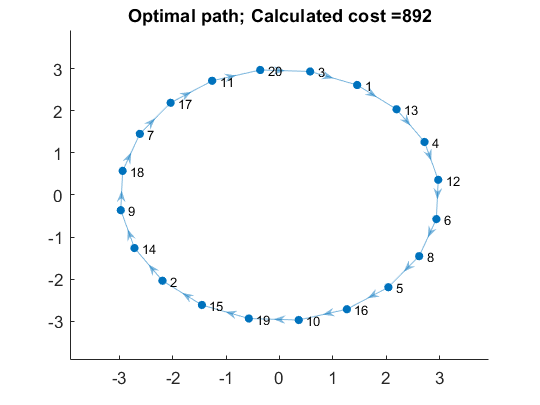

%T = @(k) -log(k+1);ttl = 'T(k)= -log(k+1)'
for l = 1:100
k = 10000; %number of iterations
X = zeros(k,m);
X(1,:) = S;
for i = 1:k
    %%%%%Permutation%%%%%%
    Y = X(i,:);
    p = randperm(m,2);
    Sp1 = Y(p(2));
    Sp2 = Y(p(1));
    Y(p(1)) = Sp1;
    Y(p(2)) = Sp2;
    %%%%%end of permutation%%%
    UY = U(Y);
    UX = U(X(i,:));
    if UY<UX
        X(i+1,:) = Y; %accept 100%
    else
        if rand()<= exp(-(UY-UX)/T(i)) %accept with probability
            X(i+1,:) = Y; 
        else
            X(i+1,:) = X(i,:); %reject
        end
    end
end

S_new = X(end,:);
S_new = circshift(S_new,-find(S_new==1)+1);
Sfinal(l,:) = S_new;
end
%%

for l=1:100
Costs(l) = U(Sfinal(l,:));
end
idx = find(Costs ==min(Costs));
S_new = Sfinal(idx,:);
%S_new = [S_new,S_new(1)];
S2 =[S_new(2:end),S_new(1)];
figure;
hold on
G = digraph(S_new,S2);
plot(G)
title('Optimal path; Calculated cost ='+string(Costs(l)))
hold off
saveas(gcf,'ex7_b_results.png')